데이타 읽어 들이기.

%['C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']

clear ;
close all;

batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

데이타중 첫번째 batch에서 하나를 선택해서 데이타 확인

%batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]
%batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]
% src = trainData(1); % src has invaild item on index 1
% dest = trainData2(8); % dest has vaild item on index 1
% merge = merge_struct(trainData(1),trainData2(8));

src = trainData(1); % src has invaild item on index 1
dest = trainData2(8); % dest has vaild item on index 1

특정데이타는 다른 batch에 나눠져 있는 경우가 있어서 이를 합쳐야 한다.

merge = merge_struct(trainData(1),trainData2(8));

% verify
src.cycle_life

ans = 1190

dest.cycle_life

ans = 663

src.cycle_life + dest.cycle_life - 1

ans = 1852

merge.cycle_life

ans = 1852

length(src.summary.QDischarge)

ans = 1189

length(dest.summary.QDischarge)

ans = 662

length(merge.summary.QDischarge)

ans = 1851

%%%%%%%%%%%
src.summary.QDischarge(1)

ans = 0

src.summary.QDischarge(2)

ans = 1.0707

src.summary.QDischarge(end-1)

ans = 1.0267

src.summary.QDischarge(end)

ans = 1.0262

%%%%
dest.summary.QDischarge(1)

ans = 1.0219

dest.summary.QDischarge(2)

ans = 1.0233

dest.summary.QDischarge(end-1)

ans = 0.8843

dest.summary.QDischarge(end)

ans = 0.8828

%%%%
merge.summary.QDischarge(1)

ans = 0

merge.summary.QDischarge(2)

ans = 1.0707

merge.summary.QDischarge(length(src.summary.QDischarge)-1)

ans = 1.0267

merge.summary.QDischarge(length(src.summary.QDischarge))

ans = 1.0262

merge.summary.QDischarge(length(src.summary.QDischarge)+1)

ans = 1.0219

merge.summary.QDischarge(length(src.summary.QDischarge)+2)

ans = 1.0233

merge.summary.QDischarge(end-1)

ans = 0.8843

merge.summary.QDischarge(end)

ans = 0.8828

test = zeros();

test = 0

test = extract_feature_all_new_bat_soc_v3(1,1,merge);

#batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))

batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))

#remove batteries that do not reach 80% capacity

del batch1['b1c8']

del batch1['b1c10']

del batch1['b1c12']

del batch1['b1c13']

del batch1['b1c22']

///////////

# There are four cells from batch1 that carried into batch2, we'll remove the data from batch2

# and put it with the correct cell from batch1

batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']

batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']

add_len = [662, 981, 1060, 208, 482];

for i, bk in enumerate(batch1_keys):

    batch1[bk]['cycle_life'] = batch1[bk]['cycle_life'] + add_len[i]

    for j in batch1[bk]['summary'].keys():

        if j == 'cycle':

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j] + len(batch1[bk]['summary'][j])))

        else:

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j]))

    last_cycle = len(batch1[bk]['cycles'].keys())

    for j, jk in enumerate(batch2[batch2_keys[i]]['cycles'].keys()):

        batch1[bk]['cycles'][str(last_cycle + j)] = batch2[batch2_keys[i]]['cycles'][jk]

del batch2['b2c7']

del batch2['b2c8']

del batch2['b2c9']

del batch2['b2c15']

del batch2['b2c16']

new_index = 1;
battery_dataset = zeros();
% 이 코드가 중요함. battery_dataset 이 structure를 가짐을 알려주어야 함.
battery_dataset = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));

% 1.1 * 0.8 = 0.88 Ah = EOL
% batch 2 = get data under 0.88 Ah - to remove this data under EOL
test2 = extract_feature_all_new_bat_soc_v3(2,1,trainData2(1));
test1 = extract_feature_all_new_bat_soc_v3(1,1,trainData(1));
test3 = extract_feature_all_new_bat_soc_v3(3,1,trainData3(1));
skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

skip_bat2 = [7 8 9 15 16 ]; % base 0 index
skip_bat2 = skip_bat2 +1; % to 1 index

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"];
batch1_fix = [1 2 3 4 5];

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        elseif ismember(batNum,batch1_fix) 
            %ismember(batNum,batch1_fix) % true or fale
            idx = find(batch1_fix==batNum);
            % find(strcmp
%             batch1_fix(idx)
%             batch2_fix(idx)
            src = trainData(batch1_fix(idx));
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            battery_dataset(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,merge);
            batNum;      
        else
            battery_dataset(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

batchNum = 2;
for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,batch2_fix) 
            batNum;
        else
            battery_dataset(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end




batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            battery_dataset(new_index) = extract_feature_all_new_bat_soc_v3(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

length(battery_dataset)

ans = 119

size(battery_dataset)

ans =      1   119


[battery_dataset.key]

ans = 1×119 string array
    "b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"   

{[battery_dataset.key]}

ans = 1×1 cell array
    {["b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"    "

contains([battery_dataset.key],'b1','IgnoreCase',true)

ans = 1×119 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


contains([battery_dataset.key],'b2','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1


contains([battery_dataset.key],'b3','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


idx1 = find(contains([battery_dataset.key],'b1','IgnoreCase',true))

idx1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36


idx2 = find(contains([battery_dataset.key],'b2','IgnoreCase',true))

idx2 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79


idx3 = find(contains([battery_dataset.key],'b3','IgnoreCase',true))

idx3 =     80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119


idx12 = [idx1 idx2]

idx12 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx13 = [idx1 idx3]

idx13 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    80    81    82    83    84    85    86    87    88    89    90    91    92    93


idx23 = [idx2 idx3]

idx23 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86


idxAll = (1:length(battery_dataset))

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx123 = [idx1 idx2 idx3]

idx123 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


key1 = [battery_dataset(idx1).key]'

key1 = 36×1 string array
    "b1c6"
    "b1c7"
    "b1c8"
    "b1c10"
    "b1c12"
    "b1c15"
    "b1c16"
    "b1c17"
    "b1c18"
    "b1c19"
    "b1c20"
    "b1c21"
    "b1c22"
    "b1c24"
    "b1c25"
    "b1c26"
    "b1c27"
    "b1c28"
    "b1c29"
    "b1c30"
    "b1c31"
    "b1c32"
    "b1c33"
    "b1c34"
    "b1c35"
    "b1c36"
    "b1c37"
    "b1c38"
    "b1c39"
    "b1c40"


key2 = [battery_dataset(idx2).key]'

key2 = 43×1 string array
    "b2c1"
    "b2c2"
    "b2c3"
    "b2c4"
    "b2c5"
    "b2c6"
    "b2c7"
    "b2c11"
    "b2c12"
    "b2c13"
    "b2c14"
    "b2c15"
    "b2c18"
    "b2c19"
    "b2c20"
    "b2c21"
    "b2c22"
    "b2c23"
    "b2c24"
    "b2c25"
    "b2c26"
    "b2c27"
    "b2c28"
    "b2c29"
    "b2c30"
    "b2c31"
    "b2c32"
    "b2c33"
    "b2c34"
    "b2c35"


key3 = [battery_dataset(idx3).key]'

key3 = 40×1 string array
    "b3c1"
    "b3c2"
    "b3c4"
    "b3c5"
    "b3c6"
    "b3c7"
    "b3c8"
    "b3c9"
    "b3c10"
    "b3c11"
    "b3c12"
    "b3c13"
    "b3c14"
    "b3c15"
    "b3c16"
    "b3c17"
    "b3c18"
    "b3c19"
    "b3c20"
    "b3c21"
    "b3c22"
    "b3c23"
    "b3c25"
    "b3c26"
    "b3c27"
    "b3c28"
    "b3c29"
    "b3c30"
    "b3c31"
    "b3c32"


input_size = 100;
ryan2_gen_dat_desc = 'ryan2_gen_dat';
save('ryan2_gen_data.mat','ryan2_gen_dat_desc');
save('ryan2_gen_data.mat','battery_dataset' ,'-append')
save('ryan2_gen_data.mat','idx1' ,'-append')
save('ryan2_gen_data.mat','idx2' ,'-append')
save('ryan2_gen_data.mat','idx3' ,'-append')
save('ryan2_gen_data.mat','idx12' ,'-append')
save('ryan2_gen_data.mat','idx23' ,'-append')
save('ryan2_gen_data.mat','idx13' ,'-append')
save('ryan2_gen_data.mat','idxAll' ,'-append')
save('ryan2_gen_data.mat','idx123' ,'-append')
save('ryan2_gen_data.mat','key1' ,'-append')
save('ryan2_gen_data.mat','key2' ,'-append')
save('ryan2_gen_data.mat','key3' ,'-append')
save('ryan2_gen_data.mat','input_size' ,'-append')


머신러닝 방법을 사용하기 위해 데이타 정규화.

이때 test set 에서도 동일한 범위로 동작하기 위해 모든 데이타에 대해 한번에 정규화해야 함.

ynorm,xnorm = training set

ytestnorm,xtestnorm = test set

idx = idxAll;
y = [battery_dataset(idx).cycle_life ]';
x = (reshape([battery_dataset(idx).Ic],100,length(y)))';
[ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate] = minmax_norm_all(y,x);

length(idx1)

ans = 36

length(idx2)

ans = 43

length(idx3)

ans = 40

length(idxAll)

ans = 119

% train  70 
% val    15
% test   15
cycle_life = [battery_dataset(idxAll).cycle_life]'

cycle_life =         1072
         634
         868
        1052
         786
         878
         717
         860
         855
         689


bat_index = [1:length(idxAll)]'

bat_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


index_cyclelife = [ bat_index, cycle_life]

index_cyclelife =            1        1072
           2         634
           3         868
           4        1052
           5         786
           6         878
           7         717
           8         860
           9         855
          10         689


% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           1072   
        2            634   
        3            868   
        4           1052   
        5            786   
        6            878   
        7            717   
        8            860   
        9            855   
       10            689   
       11            786   
       12            532   
       13            557   
       14           1012   
       15           1015   
       16            852   


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           147    
       37           299    
       40           334    
       73           428    
       78           428    
       39           437    
       41           443    
       76           456    
       46           457    
       71           458    
       51           460    
       57           460    
       75           461    
       67           462    
       70           464    
       74           465    


index =     38
    37
    40
    73
    78
    39
    41
    76
    46
    71


total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans =     38   147
    37   299
    40   334
    73   428
    78   428
    39   437
    41   443
    76   456
    46   457
    71   458


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 117

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

index_vec = [1:total_index]

index_vec =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxVal_ = index_vec(5:10:end)

idxVal_ =      5    15    25    35    45    55    65    75    85    95   105   115


idxTest_ = index_vec(6:10:end)

idxTest_ =      6    16    26    36    46    56    66    76    86    96   106   116


idxTrain_ = setdiff(index_vec,idxVal_);
idxTrain_ = setdiff(idxTrain_,idxTest_)

idxTrain_ =      1     2     3     4     7     8     9    10    11    12    13    14    17    18    19    20    21    22    23    24    27    28    29    30    31    32    33    34    37    38    39    40    41    42    43    44    47    48    49    50    51    52    53    54    57    58    59    60    61    62


idxTestTable = index_cyclelife_table_sort(idxTest_,{'bat_index'})

idxTestTable = 12×1 table
    bat_index
    _________

        39   
        74   
        77   
        43   
        36   
        26   
       117   
        18   
        22   
       101   
         1   
        95   


idxTrainTable = index_cyclelife_table_sort(idxTrain_,{'bat_index'})

idxTrainTable = 95×1 table
    bat_index
    _________

       38    
       37    
       40    
       73    
       41    
       76    
       46    
       71    
       51    
       57    
       75    
       67    
       59    
       58    
       45    
       69    


idxValTable = index_cyclelife_table_sort(idxVal_,{'bat_index'})

idxValTable = 12×1 table
    bat_index
    _________

        78   
        70   
        50   
        60   
        44   
        33   
       100   
        87   
        17   
       103   
        81   
        96   


idxTest = idxTestTable.Variables'

idxTest =     39    74    77    43    36    26   117    18    22   101     1    95


idxValid = idxValTable.Variables'

idxValid =     78    70    50    60    44    33   100    87    17   103    81    96


idxTrain = idxTrainTable.Variables'

idxTrain =     38    37    40    73    41    76    46    71    51    57    75    67    59    58    45    69    42    62    47    48    53    63    49    56    61    66    72    52    54    64    65    55    12    68   106    13    35    29    30     2    28    34    85    10    27    21    79     7    23   109


idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTrainSort = sort(idxTrain)

idxTrainSort =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    19    20    21    23    24    25    27    28    29    30    31    32    34    35    37    38    40    41    42    45    46    47    48    49    51    52    53    54    55    56    57    58    59    61    62


idxValidSort = sort(idxValid)

idxValidSort =     17    33    44    50    60    70    78    81    87    96   100   103


idxTestSort = sort(idxTest)

idxTestSort =      1    18    22    26    36    39    43    74    77    95   101   117



%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

idxTestRand =  idxTest(randperm(length(idxTest)))

idxTestRand =     74    22    26    95    77    43    36   117   101    39    18     1


idxTrainRand =  idxTrain(randperm(length(idxTrain)))

idxTrainRand =     82    11    10    73    51    54    89    63    97    16    20     9     7   115     8    58   119    91   112   104    24    59    88    35    27    62    15    47    75    85    93    94    80    21    65    45     5    64    61   108     3    67    49   113   106    68    28    55    30   107


idxValidRand =  idxValid(randperm(length(idxValid)))

idxValidRand =     96    44    50    33    87   103    17    81    70    78   100    60



%sortrows(idxValTable,{'cycle_life'},{'ascend'})

chargeCurrentIndex = [1:100]

chargeCurrentIndex =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


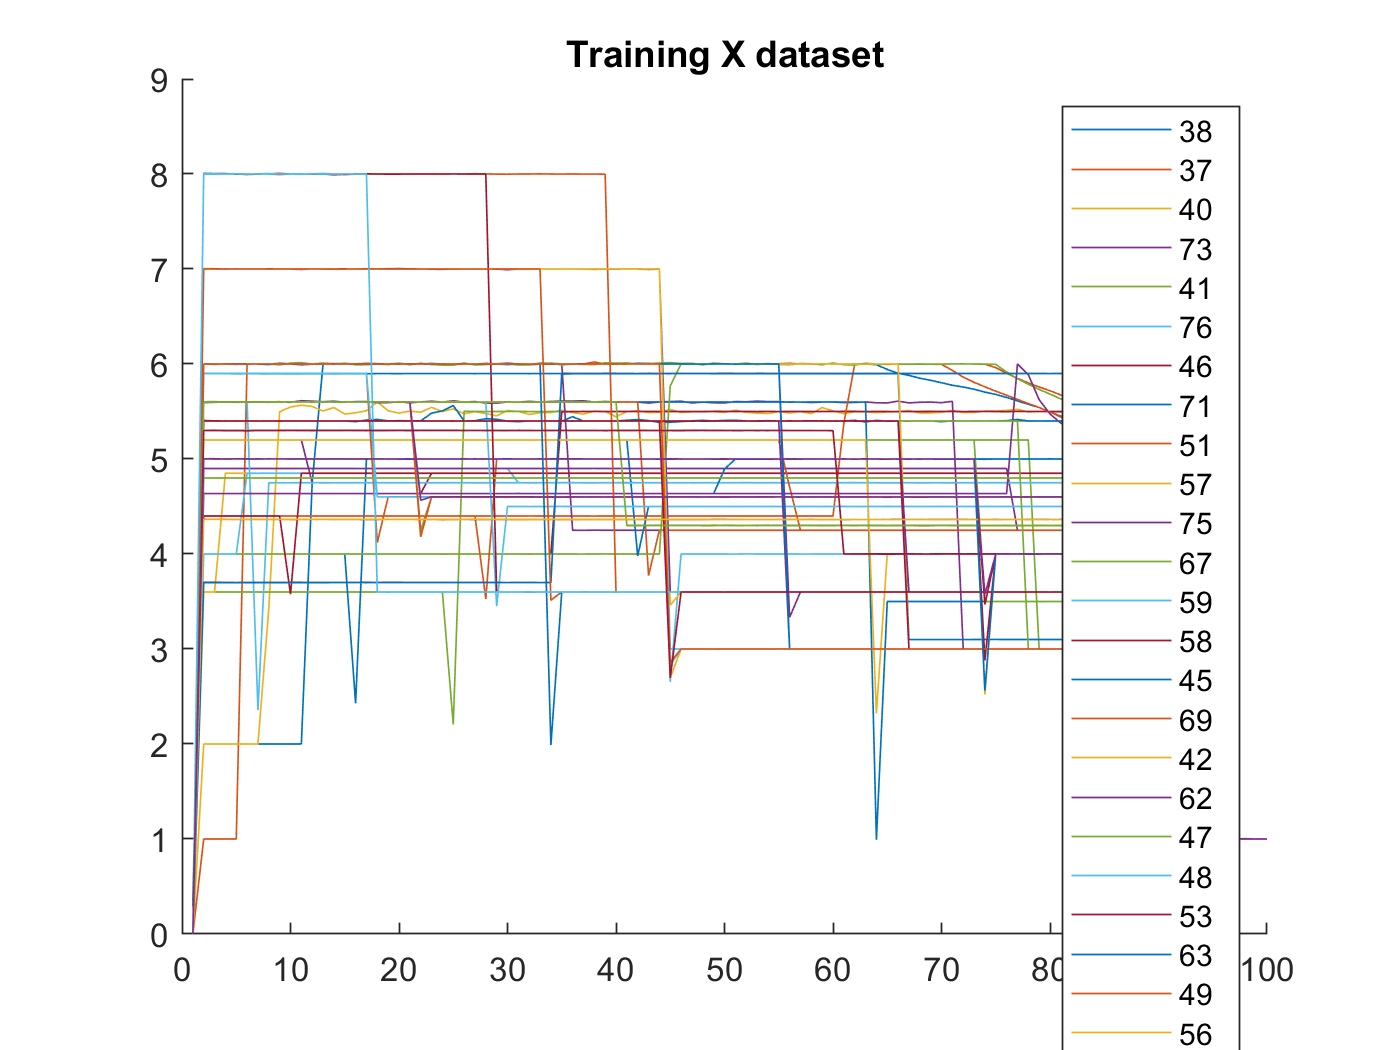

% https://blogs.mathworks.com/pick/2011/02/11/create-multi-column-plot-legends/?from=kr

nLines = length(idxTrain);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(chargeCurrentIndex,battery_dataset(i).Ic)
    legend_str{j} = num2str(i);
end
hold off
title 'Training X dataset'
legend(legend_str)%,'location','NorthWest')

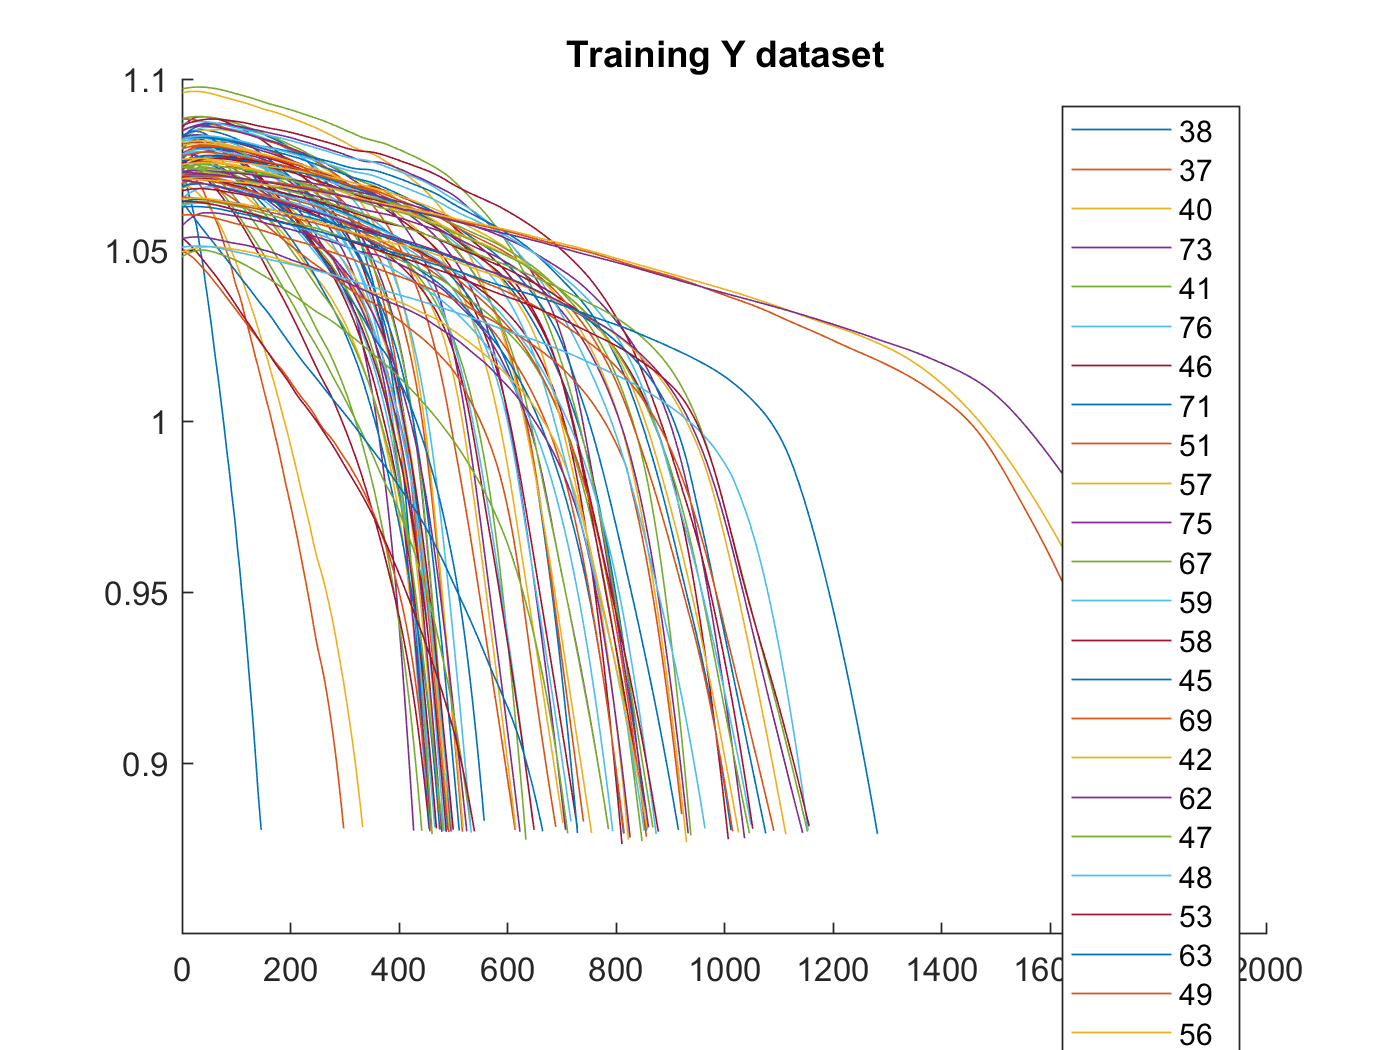


legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Training Y dataset'
legend(legend_str) %,'location','NorthWest')

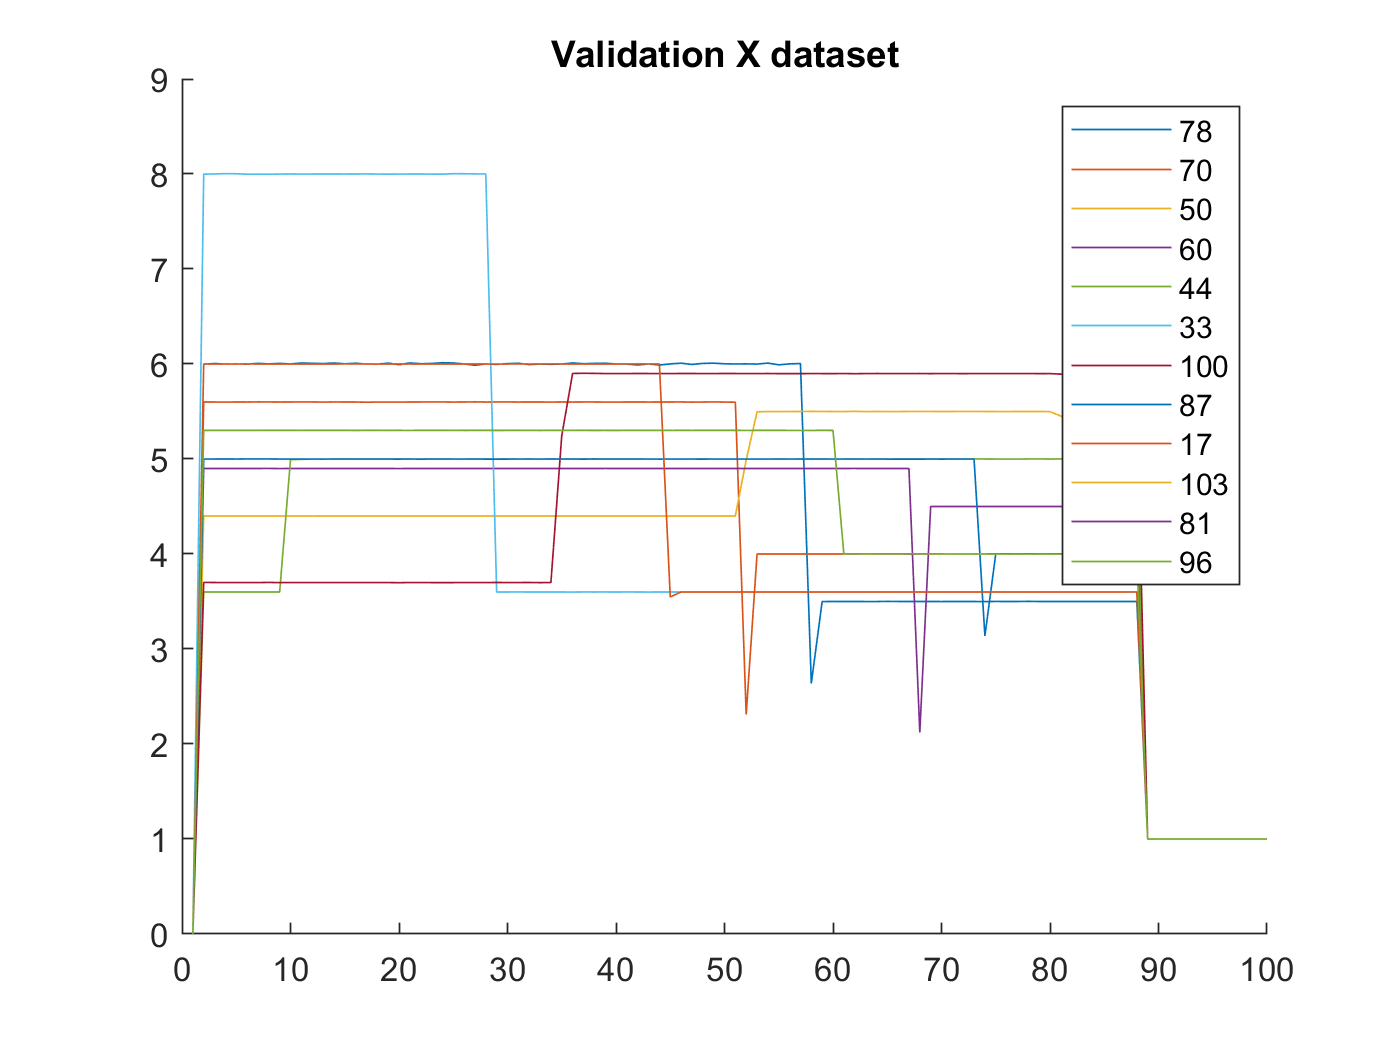



nLines = length(idxValid);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(chargeCurrentIndex,battery_dataset(i).Ic)
    legend_str{j} = num2str(i);
end
hold off
title 'Validation X dataset'
legend(legend_str)

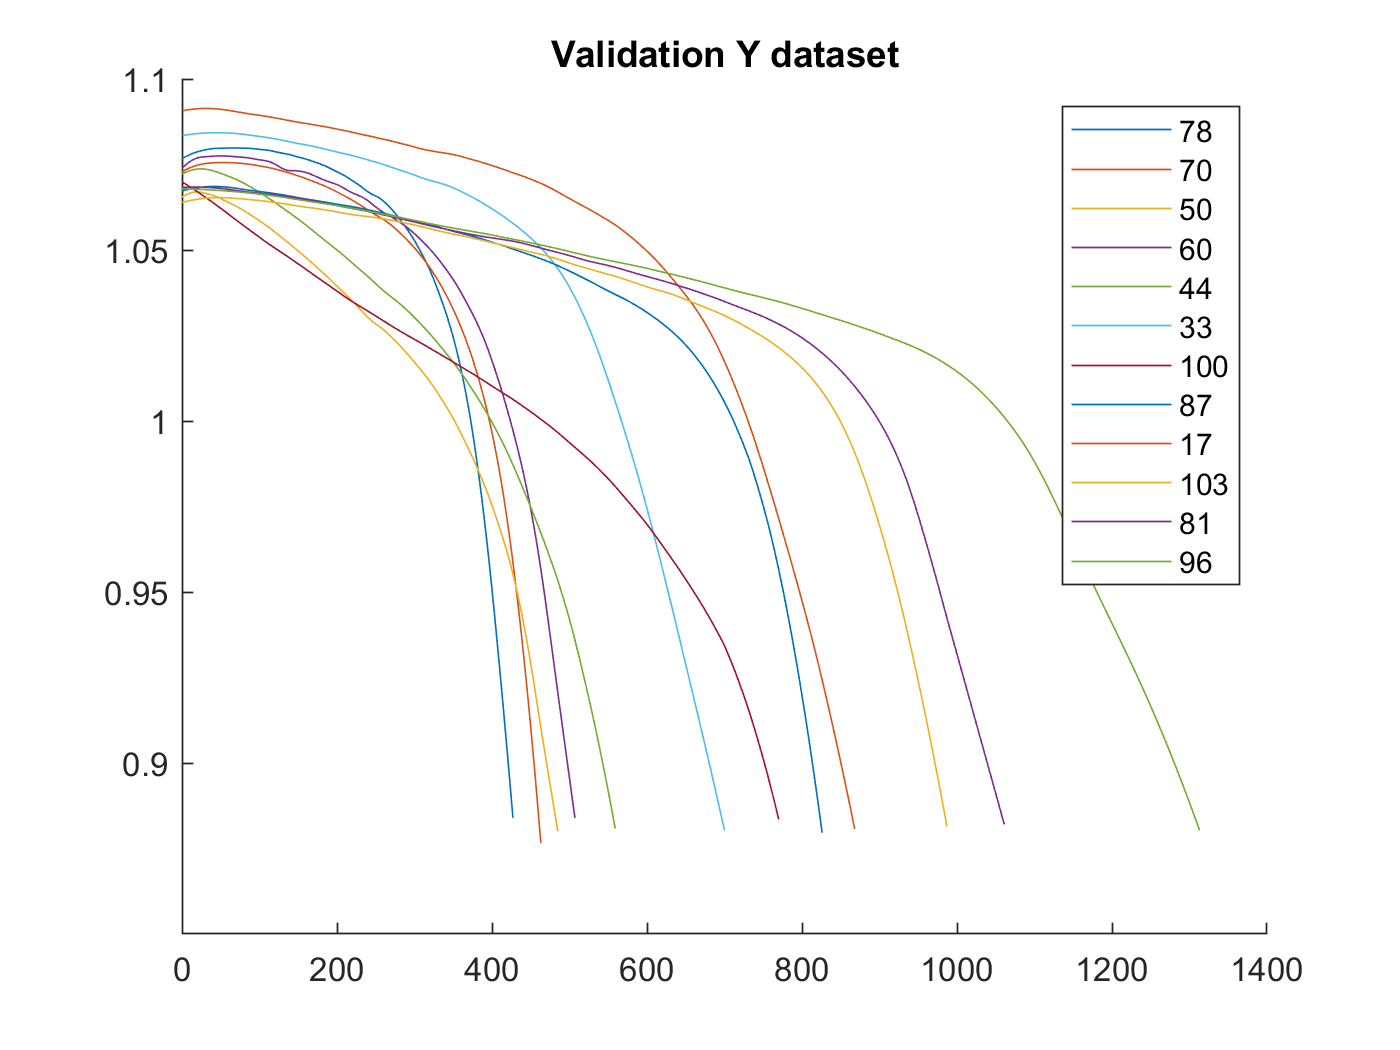


legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Validation Y dataset'
legend(legend_str)

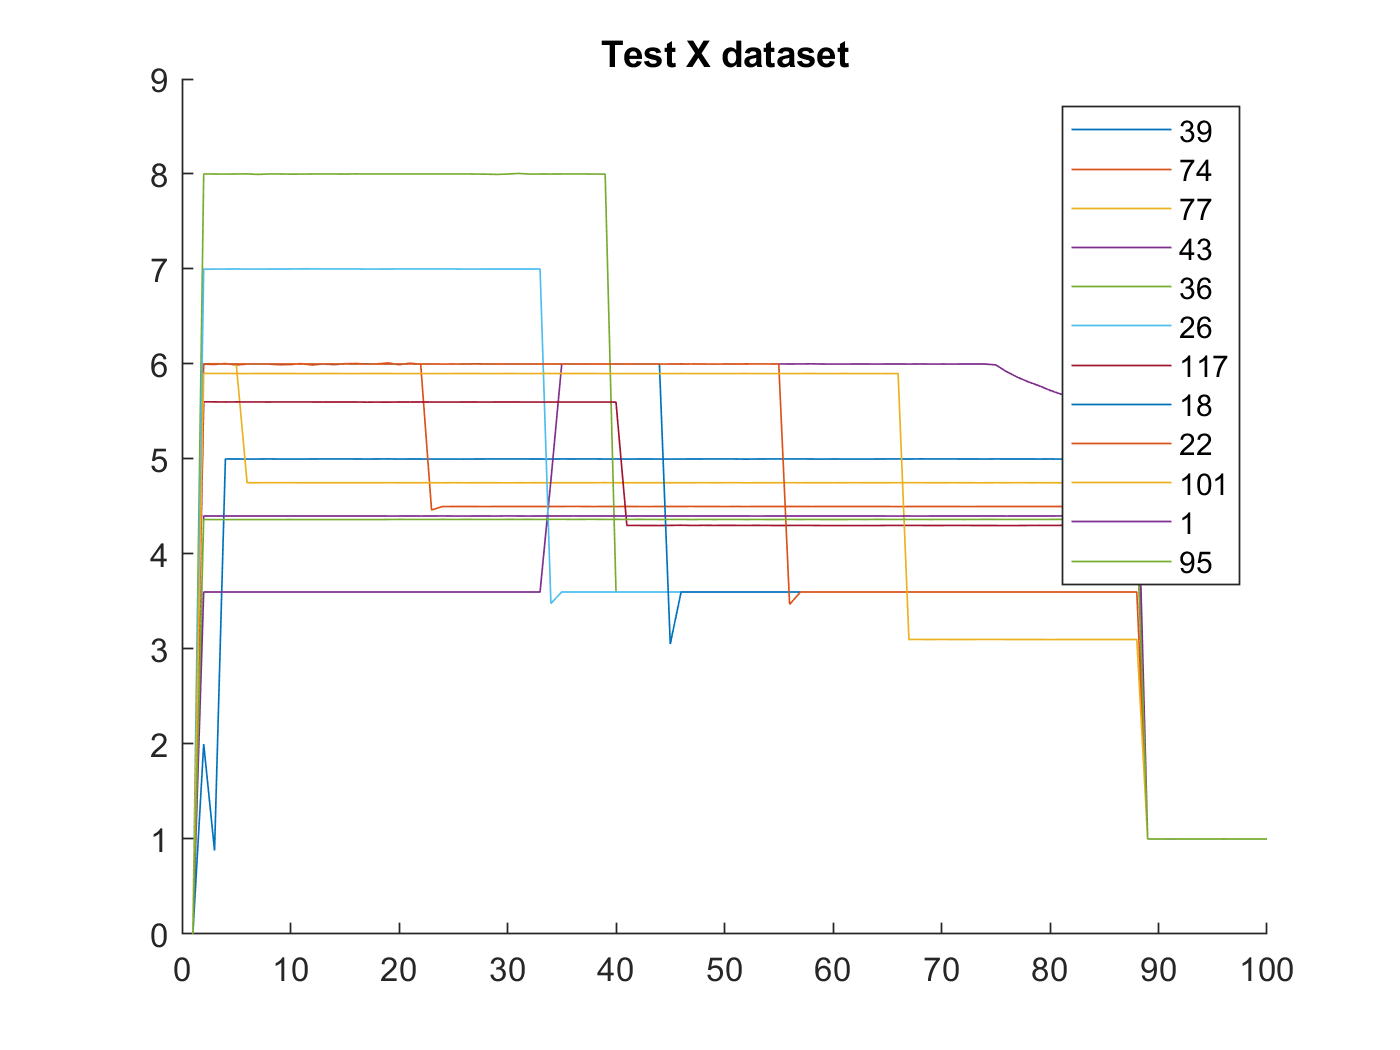


nLines = length(idxTest);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(chargeCurrentIndex,battery_dataset(i).Ic)
    legend_str{j} = num2str(i);
end
hold off
title 'Test X dataset'
legend(legend_str)

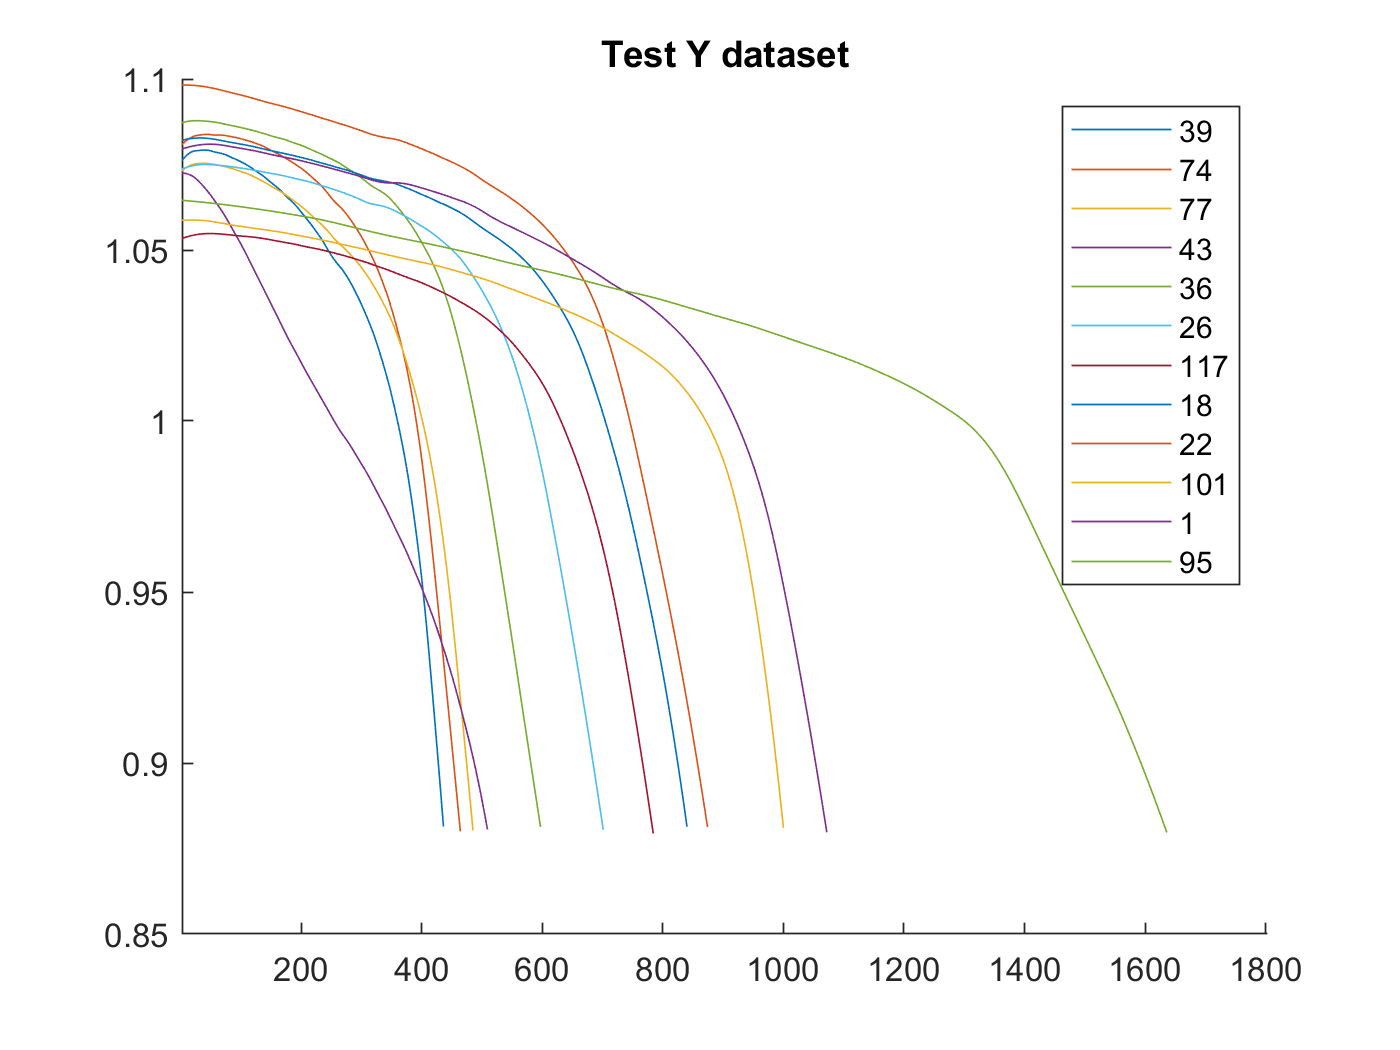


figure
hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)


save('ryan2_gen_data.mat','idxTrain' ,'-append')
save('ryan2_gen_data.mat','idxValid' ,'-append')
save('ryan2_gen_data.mat','idxTest' ,'-append')
save('ryan2_gen_data.mat','idxTrainRand' ,'-append')
save('ryan2_gen_data.mat','idxValidRand' ,'-append')
save('ryan2_gen_data.mat','idxTestRand' ,'-append')
save('ryan2_gen_data.mat','idxTrainSort' ,'-append')
save('ryan2_gen_data.mat','idxValidSort' ,'-append')
save('ryan2_gen_data.mat','idxTestSort' ,'-append')


idx = idxAll;
y = [battery_dataset(idx).cycle_life ]';
x = (reshape([battery_dataset(idx).Ic],100,length(y)))';
[ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate] = minmax_norm_all(y,x);


save('ryan2_gen_data.mat','ynormall' ,'-append')
save('ryan2_gen_data.mat','ymax' ,'-append')
save('ryan2_gen_data.mat','ymin' ,'-append')
save('ryan2_gen_data.mat','yrate' ,'-append')
save('ryan2_gen_data.mat','xnormall' ,'-append')
save('ryan2_gen_data.mat','xmax' ,'-append')
save('ryan2_gen_data.mat','xmin' ,'-append')
save('ryan2_gen_data.mat','xrate' ,'-append')

idx = idxTrain;
cycleLife_train = [battery_dataset(idx).cycle_life ]';
chargeI_train = (reshape([battery_dataset(idx).Ic],100,length(cycleLife_train)))';

idx = idxValid;
cycleLife_valid = [battery_dataset(idx).cycle_life ]';
chargeI_valid = (reshape([battery_dataset(idx).Ic],100,length(cycleLife_valid)))';

idx = [idxTrain idxValid];
cycleLife_train_valid = [battery_dataset(idx).cycle_life ]';
chargeI_train_valid = (reshape([battery_dataset(idx).Ic],100,length(cycleLife_train_valid)))';

idx = idxTest;
cycleLife_test = [battery_dataset(idx).cycle_life ]';
chargeI_test = (reshape([battery_dataset(idx).Ic],100,length(cycleLife_test)))';




save('ryan2_gen_data.mat', 'cycleLife_train'             ,'-append')
save('ryan2_gen_data.mat', 'cycleLife_valid'             ,'-append') 
save('ryan2_gen_data.mat', 'cycleLife_train_valid'       ,'-append')
save('ryan2_gen_data.mat', 'cycleLife_test'              ,'-append')
save('ryan2_gen_data.mat', 'chargeI_train'         ,'-append')
save('ryan2_gen_data.mat', 'chargeI_valid'         ,'-append')
save('ryan2_gen_data.mat', 'chargeI_train_valid'   ,'-append')
save('ryan2_gen_data.mat', 'chargeI_test'          ,'-append')           

result = zeros();
result = [0 0];

idx = idxAll

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


i=1 

i = 1

j = idx(i)

j = 1

battery_dataset(i).QDischargeSmooth(1) 

ans = 1.0795



battery_dataset_new = zeros()

battery_dataset_new = 0

battery_dataset_new = battery_dataset(1)

battery_dataset_new = struct with fields:
               policy: '4_4C-80PER_4_4C'
      policy_readable: '4.4C(80%)-4.4C'
           channel_id: "7"
           cycle_life: 1072
                  key: "b1c6"
             batchNum: 1
               batNum: 6
           chargetime: [1072×1 double]
                cycle: [1072×1 double]
                   IR: [1072×1 double]
              QCharge: [1072×1 double]
           QDischarge: [1072×1 double]
                 Tavg: [1072×1 double]
                 Tmin: [1072×1 double]
                 Tmax: [1072×1 double]
                Vdlin: [1000×1 double]
                   Vc: [1072×100 double]
                   Tc: [1072×100 double]
                   Vd: [1072×100 double]
                   Td: [1072×100 double]
              VT_leng: 100
                   Ic: [1×100 double]
                   Id: [1×100 double]
     QDischargeSmooth: [1072×1 double]
    QDischargePolyMdl: [-9.6874e-13 1.6385e-09 -9.4860e-07 1.5422e-04 1.0742]
    QDi

i=1;
for ii = 1:1000
    if battery_dataset(i).QDischargeSmooth(ii) <= 1.048
        % skip count 
        break
    end
end
ii

ii = 644

battery_dataset_new(i) = battery_dataset(i);
battery_dataset_new(i).cycle_life = battery_dataset(i).cycle_life - ii;
battery_dataset(i).cycle_life

ans = 1072

battery_dataset_new(i).cycle_life

ans = 428

battery_dataset_new(i).chargetime([1:ii],:) = [] ;

size(battery_dataset(i).chargetime)

ans =         1072           1


size(battery_dataset_new(i).chargetime)

ans =    428     1


battery_dataset_new(i).cycle = [] ;
battery_dataset_new(i).cycle = battery_dataset(i).cycle(1:end-ii,:);
battery_dataset_new(i).IR([1:ii],:) = [] ;
battery_dataset_new(i).QCharge([1:ii],:) = [] ;
battery_dataset_new(i).QDischarge([1:ii],:) = [] ;
battery_dataset_new(i).Tavg([1:ii],:) = [] ;
battery_dataset_new(i).Tmin([1:ii],:) = [] ;
battery_dataset_new(i).Tmax([1:ii],:) = [] ;
battery_dataset_new(i).Vc([1:ii],:) = [] ;
battery_dataset_new(i).Vd([1:ii],:) = [] ;
battery_dataset_new(i).Tc([1:ii],:) = [] ;
battery_dataset_new(i).Td([1:ii],:) = [] ;
battery_dataset_new(i).QDischargeSmooth([1:ii],:) = [] ;
battery_dataset_new(i).QDischargePolyMdl = [];
battery_dataset_new(i).QDischargePolyMdl = polyfit(battery_dataset_new(i).cycle, battery_dataset_new(i).QDischargeSmooth,4);
battery_dataset_new(i).QDischargePolyfit = [];
battery_dataset_new(i).QDischargePolyfit = polyval(battery_dataset_new.QDischargePolyMdl,battery_dataset_new.cycle')';


% get first capacity
for i = 1:length(idx)
    %j = idx(i);
    initC = battery_dataset(i).QDischargeSmooth(1) ;
    result(i,:) = [ i initC ];
    for ii = 1:battery_dataset(i).cycle_life
        if battery_dataset(i).QDischargeSmooth(ii) <= 1.048
            % skip count 
            break
        end
        if ii == battery_dataset(i).cycle_life
            error_is = true;
        end
    end
    battery_dataset_new(i) = battery_dataset(i);
    battery_dataset_new(i).cycle_life = battery_dataset(i).cycle_life - ii;
    %battery_dataset(i).cycle_life
    %battery_dataset_new(i).cycle_life
    battery_dataset_new(i).chargetime([1:ii],:) = [] ;
    
    %size(battery_dataset(i).chargetime)
    %size(battery_dataset_new(i).chargetime)
    battery_dataset_new(i).cycle = [] ;
    battery_dataset_new(i).cycle = battery_dataset(i).cycle(1:end-ii,:);
    battery_dataset_new(i).IR([1:ii],:) = [] ;
    battery_dataset_new(i).QCharge([1:ii],:) = [] ;
    battery_dataset_new(i).QDischarge([1:ii],:) = [] ;
    battery_dataset_new(i).Tavg([1:ii],:) = [] ;
    battery_dataset_new(i).Tmin([1:ii],:) = [] ;
    battery_dataset_new(i).Tmax([1:ii],:) = [] ;
    battery_dataset_new(i).Vc([1:ii],:) = [] ;
    battery_dataset_new(i).Vd([1:ii],:) = [] ;
    battery_dataset_new(i).Tc([1:ii],:) = [] ;
    battery_dataset_new(i).Td([1:ii],:) = [] ;
    battery_dataset_new(i).QDischargeSmooth([1:ii],:) = [] ;
    battery_dataset_new(i).QDischargePolyMdl = [];
    battery_dataset_new(i).QDischargePolyMdl = polyfit(battery_dataset_new(i).cycle, battery_dataset_new(i).QDischargeSmooth,4);
    battery_dataset_new(i).QDischargePolyfit = [];
    battery_dataset_new(i).QDischargePolyfit = polyval(battery_dataset_new(i).QDischargePolyMdl,battery_dataset_new(i).cycle')';


end
result 

result =     1.0000    1.0795
    2.0000    1.0800
    3.0000    1.0971
    4.0000    1.0864
    5.0000    1.0572
    6.0000    1.0744
    7.0000    1.0652
    8.0000    1.0848
    9.0000    1.0754
   10.0000    1.0682


max(result(:,2))

ans = 1.0982

min(result(:,2))

ans = 1.0480

ryan2_gen_data_new_desc = 'ryan2_gen_data_new';
save('ryan2_gen_data_new.mat','ryan2_gen_data_new_desc');
save('ryan2_gen_data_new.mat','battery_dataset_new' ,'-append')

idx = idxAll;
y = [battery_dataset_new(idx).cycle_life ]';
x = (reshape([battery_dataset_new(idx).Ic],100,length(y)))';
[ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate] = minmax_norm_all(y,x);

length(idx1)

ans = 36

length(idx2)

ans = 43

length(idx3)

ans = 40

length(idxAll)

ans = 119

% train  70 
% val    15
% test   15
cycle_life = [battery_dataset_new(idxAll).cycle_life]'

cycle_life =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


bat_index = [1:length(idxAll)]'

bat_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


index_cyclelife = [ bat_index, cycle_life]

index_cyclelife =      1   428
     2   229
     3   253
     4   338
     5   416
     6   331
     7   278
     8   235
     9   284
    10   462


% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           428    
        2           229    
        3           253    
        4           338    
        5           416    
        6           331    
        7           278    
        8           235    
        9           284    
       10           462    
       11           269    
       12           379    
       13           300    
       14           354    
       15           405    
       16           316    


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           109    
       78           115    
       71           118    
       69           129    
       65           137    
       76           140    
       61           146    
       74           146    
       73           152    
       66           153    
       70           153    
       64           154    
       68           155    
       75           157    
       63           161    
       48           168    


index =     38
    78
    71
    69
    65
    76
    61
    74
    73
    66




total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans =     38   109
    78   115
    71   118
    69   129
    65   137
    76   140
    61   146
    74   146
    73   152
    66   153


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 116

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

new_idx_vec = [1:total_index]

new_idx_vec =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


new_idxVal_ = new_idx_vec(5:10:end)

new_idxVal_ =      5    15    25    35    45    55    65    75    85    95   105   115


new_idxTest_ = new_idx_vec(6:10:end)

new_idxTest_ =      6    16    26    36    46    56    66    76    86    96   106   116


new_idxTrain_ = setdiff(new_idx_vec,new_idxVal_);
new_idxTrain_ = setdiff(new_idxTrain_,new_idxTest_)

new_idxTrain_ =      1     2     3     4     7     8     9    10    11    12    13    14    17    18    19    20    21    22    23    24    27    28    29    30    31    32    33    34    37    38    39    40    41    42    43    44    47    48    49    50    51    52    53    54    57    58    59    60    61    62


new_idxTestTable = index_cyclelife_table_sort(new_idxTest_,{'bat_index'})

new_idxTestTable = 12×1 table
    bat_index
    _________

        76   
        48   
        62   
        28   
        26   
        47   
        16   
        99   
        92   
       106   
        84   
       119   


new_idxTrainTable = index_cyclelife_table_sort(new_idxTrain_,{'bat_index'})

new_idxTrainTable = 95×1 table
    bat_index
    _________

       38    
       78    
       71    
       69    
       61    
       74    
       73    
       66    
       70    
       64    
       68    
       75    
       52    
       60    
       30    
       36    


new_idxValTable = index_cyclelife_table_sort(new_idxVal_,{'bat_index'})

new_idxValTable = 12×1 table
    bat_index
    _________

        65   
        63   
        56   
        59   
        40   
        11   
        46   
        14   
        94   
        10   
       100   
       115   


new_idxTest = new_idxTestTable.Variables'

new_idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


new_idxValid = new_idxValTable.Variables'

new_idxValid =     65    63    56    59    40    11    46    14    94    10   100   115


new_idxTrain = new_idxTrainTable.Variables'

new_idxTrain =     38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25    27    33    53     2    22     8    57    23    55    45     3    17    34    41   109    18     7     9    13    93



new_idxTrainSort = sort(new_idxTrain)

new_idxTrainSort =      1     2     3     4     5     6     7     8     9    12    13    15    17    18    19    20    21    22    23    24    25    27    29    30    31    32    33    34    35    36    37    38    39    41    42    43    44    45    49    50    51    52    53    54    55    57    58    60    61    64


new_idxValidSort = sort(new_idxValid)

new_idxValidSort =     10    11    14    40    46    56    59    63    65    94   100   115


new_idxTestSort = sort(new_idxTest)

new_idxTestSort =     16    26    28    47    48    62    76    84    92    99   106   119



%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

new_idxTestRand =  new_idxTest(randperm(length(new_idxTest)))

new_idxTestRand =     28    48    92   106    84    47    16   119    99    62    76    26


new_idxTrainRand =  new_idxTrain(randperm(length(new_idxTrain)))

new_idxTrainRand =    116     9    68    30     3    82    80    79    70   103    58    45     1     2    93    32    35    78    88    85    90    42    43    86    13    64    67    87    73    55     8    37    29    77    52   114    23    21    41    51    36    17    81    12    24    95   113    83     6     7


new_idxValidRand =  new_idxValid(randperm(length(new_idxValid)))

new_idxValidRand =     56    46   100    11    14    10    59    94   115    65    63    40



%sortrows(new_idxValTable,{'cycle_life'},{'ascend'})

save('ryan2_gen_data_new.mat','new_idxTrain' ,'-append')
save('ryan2_gen_data_new.mat','new_idxValid' ,'-append')
save('ryan2_gen_data_new.mat','new_idxTest' ,'-append')
save('ryan2_gen_data_new.mat','new_idxTrainRand' ,'-append')
save('ryan2_gen_data_new.mat','new_idxValidRand' ,'-append')
save('ryan2_gen_data_new.mat','new_idxTestRand' ,'-append')
save('ryan2_gen_data_new.mat','new_idxTrainSort' ,'-append')
save('ryan2_gen_data_new.mat','new_idxValidSort' ,'-append')
save('ryan2_gen_data_new.mat','new_idxTestSort' ,'-append')


idx = idxAll;
new_y = [battery_dataset_new(idx).cycle_life ]';
new_x = (reshape([battery_dataset_new(idx).Ic],100,length(new_y)))';
[new_ynormall,new_ymax,new_ymin,new_yrate,new_xnormall,new_xmax,new_xmin,new_xrate] = minmax_norm_all(new_y,new_x);


save('ryan2_gen_data_new.mat','new_ynormall' ,'-append')
save('ryan2_gen_data_new.mat','new_ymax' ,'-append')
save('ryan2_gen_data_new.mat','new_ymin' ,'-append')
save('ryan2_gen_data_new.mat','new_yrate' ,'-append')
save('ryan2_gen_data_new.mat','new_xnormall' ,'-append')
save('ryan2_gen_data_new.mat','new_xmax' ,'-append')
save('ryan2_gen_data_new.mat','new_xmin' ,'-append')
save('ryan2_gen_data_new.mat','new_xrate' ,'-append')

idx = new_idxTrain;
new_cycleLife_train = [battery_dataset_new(idx).cycle_life ]';
new_chargeI_train = (reshape([battery_dataset_new(idx).Ic],100,length(new_cycleLife_train)))';

idx = new_idxValid;
new_cycleLife_valid = [battery_dataset_new(idx).cycle_life ]';
new_chargeI_valid = (reshape([battery_dataset_new(idx).Ic],100,length(new_cycleLife_valid)))';

idx = [new_idxTrain new_idxValid];
new_cycleLife_train_valid = [battery_dataset_new(idx).cycle_life ]';
new_chargeI_train_valid = (reshape([battery_dataset_new(idx).Ic],100,length(new_cycleLife_train_valid)))';

idx = new_idxTest;
new_cycleLife_test = [battery_dataset_new(idx).cycle_life ]';
new_chargeI_test = (reshape([battery_dataset_new(idx).Ic],100,length(new_cycleLife_test)))';




save('ryan2_gen_data_new.mat', 'new_cycleLife_train'             ,'-append')
save('ryan2_gen_data_new.mat', 'new_cycleLife_valid'             ,'-append') 
save('ryan2_gen_data_new.mat', 'new_cycleLife_train_valid'       ,'-append')
save('ryan2_gen_data_new.mat', 'new_cycleLife_test'              ,'-append')
save('ryan2_gen_data_new.mat', 'new_chargeI_train'        		 ,'-append')
save('ryan2_gen_data_new.mat', 'new_chargeI_valid'        		 ,'-append')
save('ryan2_gen_data_new.mat', 'new_chargeI_train_valid'  		 ,'-append')
save('ryan2_gen_data_new.mat', 'new_chargeI_test'         		 ,'-append')     
